clear all
close all
clc

% Single Param
directory = 'Snake_Evolution_Results30-Aug-alpha' % b

directory = 'Snake_Evolution_Results30-Aug-alpha'

%directory = 'Snake_Evolution_Results30-Aug-d' % b
%directory = 'Snake_Evolution_Results30-Aug-n' %b

%directory = 'Snake_Evolution_Results22-Aug-2024_20_53_14'
%cd('Snake_Evolution_Results22-Aug-2024_20_53_14')

prefix = 'Design'

prefix = 'Design'

files = dir(fullfile(directory, [prefix, '*.mat']));

%Snake1{1} = 'Snake_Evolution_Results22-Aug-2024_20_53_14 Finished_22-Aug-2024_21_01_21.mat';

% Single Param (b)
Snake1{1} = 'Snake_Evolution_Results30-Aug-2024_11_56_48 Finished_30-Aug-2024_12_01_00.mat'; % alpha
%Snake1{1} = 'Snake_Evolution_Results30-Aug-2024_10_16_57 Finished_30-Aug-2024_10_53_19.mat'; % d
%Snake1{1} = 'Snake_Evolution_Results30-Aug-2024_12_05_01 Finished_30-Aug-2024_12_06_19.mat'; % n




for i = 1:86
    Snake1{i} = files(i).name;
    V(i) = load(Snake1{i});
    data(i, 1) = V(i).max_dexterity(1);
    data(i, 2) = V(i).Design_params.alpha;  
    data(i, 3) = V(i).Design_params.d; 
    data(i, 4) = V(i).Design_params.n; 
    data(i, 5) = V(i).Design_params.w; 
end


sortedArray = sortrows(data, 2, 'ascend')

sortedArray =     0.0062    0.0100    2.1100    3.0000    3.0000
    0.0123    0.0300    2.1100    3.0000    3.0000
    0.0123    0.0500    2.1100    3.0000    3.0000
    0.0247    0.0700    2.1100    3.0000    3.0000
    0.0123    0.0800    2.1100    3.0000    3.0000
    0.0123    0.0900    2.1100    3.0000    3.0000
    0.0247    0.1000    2.1100    3.0000    3.0000
    0.0185    0.1300    2.1100    3.0000    3.0000
    0.0123    0.1400    2.1100    3.0000    3.0000
    0.0123    0.1600    2.1100    3.0000    3.0000


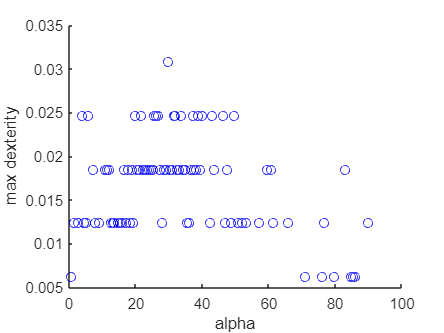

figure
scatter(rad2deg(sortedArray(:,2)), sortedArray(:,1), 'b')
xlabel('alpha')
ylabel('max dexterity')

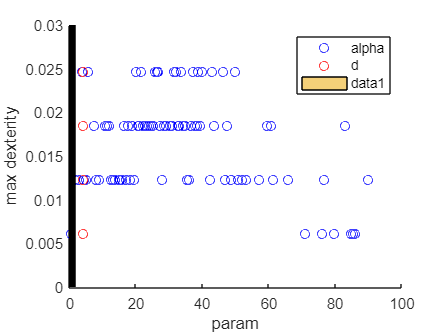

% scatter(rad2deg(sortedArray(:,2)), sortedArray(:,1), 'b')
% hold on
% scatter(2*sortedArray(:,3), sortedArray(:,1), 'r')
% xlabel('param')
% ylabel('max dexterity')
% legend('alpha', 'd')
% ylim([0,0.03])
% histogram(sortedArray(:,2))
% hold off

% 
% %scatter3(sortedArray(:,2), sortedArray(:,3), sortedArray(:,4) 50, sortedArray(:,1), 'filled');
% xlabel('Parameter 1 Name');
% ylabel('Parameter 2 Name');
% zlabel('Parameter 3 Name');
% title('3D Scatter: Design Parameters vs. Dexterity');
% colorbar;





% dataMatrix = sortedArray; % [sortedArray(:,2), sortedArray(:,3), sortedArray(:,4),  sortedArray(:,1)];
% labels = {'Param 1', 'Param 2', 'Param 3', 'Dexterity'};
% plotmatrix(dataMatrix);
% 
% 



